%hallem_set = hallem.load_hallem_set()
Hallem = hallem.HallemSet();

hinds = [5,8,10,13,39,40,46,47,51,53,58,62,65,68,73,74,75,79,89,91,94,97,100,105];


hinds = [5,8,10,13,39,40,46,47,51,53,58,62,65,68,73,74,75,79,89,91,94,97,100,105];

%hinds = unique(hi);
%hinds(hinds==111)=[];
chem_cat = Hallem.T.type(1:110);

% opts = statset('OutputFcn',@(optimValues,state) KLLogging(optimValues,state,chem_cat),...
%                 'MaxIter', 5000,...
%                 'Display', 'final');
X = Hallem.T{1:110, Hallem.receptor.all};
[Y, loss] = tsne(X, 'Distance', 'correlation', 'Standardize', true);

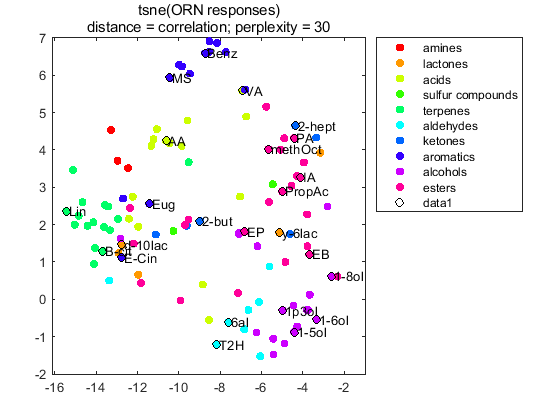

figure
hs = gscatter(Y(:,1),Y(:,2),Hallem.chem.cat_list(chem_cat));
legend('Location', 'northeastoutside');

hold on
scatter(Y(hinds,1), Y(hinds,2), 'ko', 'LineWidth', 1);

[hl,ext] = labelpoints(Y(hinds,1), Y(hinds,2),...
                       Hallem.odors.abbrev(hinds),...
                       'position', 'E',...
                       'buffer', .08,...
                       'FontSize', 10,...
                       'adjust_axes', 1);
title(["tsne(ORN responses)"; "distance = correlation; perplexity = 30"]);
set(gcf, 'renderer', 'painters');